# Homework 6

A = readmatrix("HW6_A.xlsx");
B = [2; 0; 1.5; 0];
C = [1 0 2 0];
D = 0;

AA = [A B; C 0] ;
bb = [0; 0; 0; 0; 1] ;
n = size(A,1);   % state dimension = 4

## part (a) fall state regulator and estimator

% Open-loop poles
ol_poles = eig(A);
fprintf('Open-loop poles:\n'); disp(ol_poles)

Open-loop poles:
  -1.0000 + 9.0000i
  -1.0000 - 9.0000i
  -4.0000 + 0.0000i
 -12.0000 + 0.0000i



The open-loop eignvalues are $\lambda \left(A\right)=\left\lbrace -1\pm 9i,-4,-12\right\rbrace \;\mathrm{rad}\;/s$ 

Since the state of the plant can not be measuered, control law we use estimated state $\hat{x\;}$ from the estimator. 


$$u=-K\hat{x}$$
 

To achieve undamping, we choose a damping ratio of $\zeta =0\ldotp 7$based on Figure 3.19 (Frankin). We want the settling time less than 1 seconds, we pick the situation of 5%

Settling time $e^{-\zeta \omega_n t_s } =0\ldotp 05\to t_s =\frac{3}{\zeta \;\omega_n }=\frac{3}{\sigma }$ 

so $\zeta =\sigma \ge 3\ldotp 333$. For measure of safety, we chose $\zeta \omega_n =\sigma =5$. since $\zeta =0\ldotp 7,$$\omega_n =7\ldotp 07$


$$s=-\zeta \omega_n \pm j\omega_n \sqrt{1-\zeta {\;}^2 }=-5\pm 5j$$


the dominant poles we choose is $\left\lbrace -5\pm 5j\right\rbrace \ldotp$ Two non-dominant poles are placed at $\left\lbrace -10,-15\right\rbrace$.$\left(2-4\times \mathrm{faster}\;\mathrm{than}\;\mathrm{the}\;\mathrm{dominant}\;\mathrm{poles}\right)$.

% Regulator poles (well into LHP, good damping)
reg_poles = [-5+5i, -5-5i, -10, -15];
K = place(A, B, reg_poles);
fprintf('State feedback gain K:\n'); disp(K);

State feedback gain K:
    8.8579    0.7343   -0.4771    6.3417



fprintf('Closed-loop (regulator) poles:\n'); disp(eig(A - B*K));

Closed-loop (regulator) poles:
 -15.0000 + 0.0000i
  -5.0000 + 5.0000i
  -5.0000 - 5.0000i
 -10.0000 + 0.0000i




% Observer poles (3-7x faster than regulator)
obs_poles = [-20+8i; -20-8i; -25+5i; -25-5i];
L = place(A', C', obs_poles)';
fprintf('Observer gain L:\n'); disp(L);

Observer gain L:
   14.2225
 -165.7479
   28.8887
  165.6131



fprintf('Observer (A-LC) poles:\n'); disp(eig(A - L*C));

Observer (A-LC) poles:
 -25.0000 + 5.0000i
 -25.0000 - 5.0000i
 -20.0000 + 8.0000i
 -20.0000 - 8.0000i



## part (b) reference tracking system

The estimator : $\dot{\hat{x} } =\left(A-\mathrm{LC}-\mathrm{BK}\right)\hat{x} +\mathrm{Ly}+B\bar{N} r$

control law : $u=-K\hat{x} +\bar{N} r\ldotp$


$$\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{\hat{x} } 
\end{array}\right\rbrack =\underset{A_{\mathrm{cl},b} }{\underbrace{\left\lbrack \begin{array}{cc}
A & -\mathrm{BK}\\
C & A-\mathrm{BK}-\mathrm{LC}
\end{array}\right\rbrack } } \left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack +\underset{B_{\mathrm{cl},b} }{\underbrace{\left\lbrack \begin{array}{c}
B\bar{N} \\
B\bar{N} 
\end{array}\right\rbrack } } r$$



$$y=\underset{C_{\mathrm{cl},b} }{\underbrace{\left\lbrack \begin{array}{cc}
C & 0
\end{array}\right\rbrack } } \left\lbrack \begin{array}{c}
\dot{x} \\
\dot{\hat{x} } 
\end{array}\right\rbrack$$


xx = AA \ bb; 

Nx = xx(1:4);
Nu = xx(5);
N_bar = Nu+ K * Nx;
display(Nx);

Nx =    -0.1947
   -0.1472
    0.5973
    0.4654


display(Nu);

Nu = 0.9208

display(Nbar);

Nbar = 0.8983


Acl_b = [A,       -B*K;
         L*C,   A-L*C-B*K];

Bcl_b = [B*N_bar;  
         B*N_bar];  

Ccl_b = [C, zeros(1,n)];
Dcl_b = 0;

sys_b = ss(Acl_b, Bcl_b, Ccl_b, Dcl_b);  %delete the simicolon to show the system
fprintf('Part (b) closed-loop poles:\n'); disp(eig(Acl_b));

Part (b) closed-loop poles:
  -5.0000 + 5.0000i
  -5.0000 - 5.0000i
 -25.0000 + 5.0000i
 -25.0000 - 5.0000i
 -10.0000 + 0.0000i
 -15.0000 + 0.0000i
 -20.0000 + 8.0000i
 -20.0000 - 8.0000i



## part (c) robust tracking


$$\begin{array}{l}
\dot{x_I } =\mathrm{Cx}-r\left(=e\right)\\
\dot{\;x} =\mathrm{Ax}+\mathrm{Bu}=\mathrm{Ax}+B\left(-K_1 x_I -K_0 \hat{x} \right)\\
u=-K_1 x_I -K_0 \hat{x} \\
\dot{\hat{x} } =A\hat{x} +\mathrm{Bu}+L\left(y-C\hat{x\;} \right)=\left(A-{\mathrm{BK}}_0 -\mathrm{CL}\right)\hat{x} -{\mathrm{BK}}_1 x_I +\mathrm{CLx}
\end{array}$$



$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\dot{\;x_I } \\
\dot{\;x} \\
\dot{\hat{x\;} } 
\end{array}\right\rbrack =\underset{A_{\textrm{aug}} }{\underbrace{\left\lbrack \begin{array}{ccc}
0 & C & 0\\
-{\textrm{BK}}_1  & A & -{\textrm{BK}}_0 \\
-{\textrm{BK}}_1  & \textrm{LC} & A-{\textrm{BK}}_0 -\textrm{LC}
\end{array}\right\rbrack } } \left\lbrack \begin{array}{c}
x_I \\
x\\
\hat{x\;} 
\end{array}\right\rbrack +\underset{B_{\textrm{aug}} }{\underbrace{\left\lbrack \begin{array}{c}
-1\\
0\\
0
\end{array}\right\rbrack } } r\\
y=\underset{C_{\textrm{aug}} }{\underbrace{\left\lbrack \begin{array}{ccc}
0 & C & 0
\end{array}\right\rbrack } } \left\lbrack \begin{array}{c}
x_I \\
x\\
\hat{x\;} 
\end{array}\right\rbrack 
\end{array}$$


A_ext = [0,  C ;      
         zeros(n,1), A];  
B_ext = [0; B];           
C_ext = [0, C];           
fprintf('Extended system controllability rank: %d (should be %d)\n', rank(ctrb(A_ext, B_ext)), n+1);

Extended system controllability rank: 5 (should be 5)


 
% Regulator poles for extended system (5 poles needed)
reg_poles_ext = [-5+5i, -5-5i, -10, -15, -20];
K_ext = place(A_ext, B_ext, reg_poles_ext);
 
K1 = K_ext(1);        % integrator gain (scale)
K0 = K_ext(2:end);    % state-feedback gain (1×4)

fprintf('K1 (integrator gain) = %.4f\n', K1);

K1 (integrator gain) = 35.0908


fprintf('K0 (state gains) = [%s]\n', num2str(K0));

K0 (state gains) = [12.05      6.93785      8.60006      4.52909]


 
% Observer for original plant (same as part a)
% u = -K_0*x_hat - K_1*x_i, with x_hat from observer
 
% Full augmented state for simulation: z = [x_I; x; x_hat]  (9 states)
A_aug_c = [ 0,      C,              zeros(1,n)  ;
           -B*K1,   A,              -B*K0       ;
           -B*K1,   L*C,    (A - L*C - B*K0)   ];

B_aug_c = [-1; zeros(n,1); zeros(n,1)];  
C_aug_c = [0, C, zeros(1,n)];           

sys_c = ss(A_aug_c, B_aug_c, C_aug_c, 0)


sys_c =
 
  A = 
             x1        x2        x3        x4        x5        x6        x7        x8        x9
   x1         0         1         0         2         0         0         0         0         0
   x2    -70.18    -5.778    -3.528    -5.788  -0.06132     -24.1    -13.88     -17.2    -9.058
   x3         0     12.16    -6.094  -0.04245     3.212         0         0         0         0
   x4    -52.64     11.16      7.66    -5.953     11.76    -18.07    -10.41     -12.9    -6.794
   x5         0     8.939     3.189     3.835   -0.1745         0         0         0         0
   x6    -70.18     14.22         0     28.45         0     -44.1     -17.4    -51.43     -9.12
   x7         0    -165.7         0    -331.5         0     177.9    -6.094     331.5     3.212
   x8    -52.64     28.89         0     57.78         0     -35.8    -2.746    -76.63     4.971
   x9         0     165.6         0     331.2         0    -156.7     3.189    -327.4   -0.1745
 
  B = 
       u1
   

## part (d) Unit step response

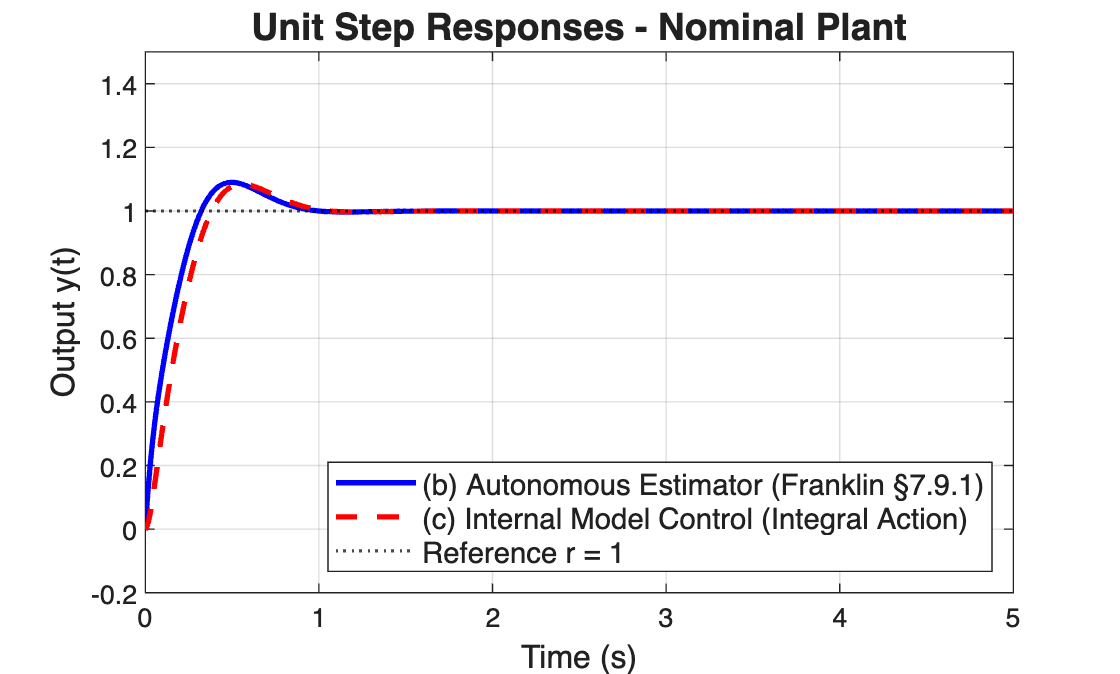

t = linspace(0, 5, 1000);
 
[y_b, t_b] = step(sys_b, t);
[y_c, t_c] = step(sys_c, t);
 
figure('Name','Part (d): Step Responses - Nominal Plant','NumberTitle','off');
plot(t_b, y_b, 'b-',  'LineWidth', 2); hold on;
plot(t_c, y_c, 'r--', 'LineWidth', 2);
yline(1, 'k:', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)', 'FontSize', 12);
ylabel('Output y(t)', 'FontSize', 12);
title('Unit Step Responses - Nominal Plant', 'FontSize', 14);
legend('(b) Autonomous Estimator (Franklin §7.9.1)', ...
       '(c) Internal Model Control (Integral Action)', ...
       'Reference r = 1', ...
       'Location', 'southeast', 'FontSize', 11);
xlim([0 5]); ylim([-0.2 1.5]);

 
% Steady-state values
fprintf('Steady-state y_b(5s) = %.4f\n', y_b(end));

Steady-state y_b(5s) = 1.0000


fprintf('Steady-state y_c(5s) = %.4f\n', y_c(end));

Steady-state y_c(5s) = 1.0000


## part (e) Robustness: Aged Plant

aging_factor = 1.50;          % 50 % increase in A
A_aged = aging_factor * A;

% --- (b) with aged plant: estimator/regulator/Nbar all use original A ---
Acl_b_aged = [A_aged,   -B*K;
              L*C,      A - L*C - B*K];
Bcl_b_aged = [B*Nbar;
              B*Nbar];
Ccl_b_aged = [C, zeros(1,n)];
sys_b_aged = ss(Acl_b_aged, Bcl_b_aged, Ccl_b_aged, 0);

fprintf('\n=== (e) Aged-plant closed-loop poles ===\n');


=== (e) Aged-plant closed-loop poles ===


fprintf('Part (b) aged poles:\n'); disp(eig(Acl_b_aged));

Part (b) aged poles:
 -45.5923 +18.5940i
 -45.5923 -18.5940i
  -9.4829 +27.5555i
  -9.4829 -27.5555i
  -4.5527 + 4.4575i
  -4.5527 - 4.4575i
  -7.3720 + 4.4999i
  -7.3720 - 4.4999i




% --- (c) with aged plant: integrator + observer (designed for original A) ---
A_aug_c_aged = [ 0,        C,            zeros(1,n)  ;
                -B*K1,     A_aged,       -B*K0       ;
                -B*K1,     L*C,          A - L*C - B*K0 ];
B_aug_c_aged = [-1; zeros(n,1); zeros(n,1)];
C_aug_c_aged = [0, C, zeros(1,n)];
sys_c_aged = ss(A_aug_c_aged, B_aug_c_aged, C_aug_c_aged, 0);

fprintf('Part (c) aged poles:\n'); disp(eig(A_aug_c_aged));

Part (c) aged poles:
 -49.1491 + 0.0000i
 -34.9593 +25.2829i
 -34.9593 -25.2829i
  -5.5688 +23.6450i
  -5.5688 -23.6450i
  -5.0271 + 4.1378i
  -5.0271 - 4.1378i
  -6.8703 + 4.4175i
  -6.8703 - 4.4175i



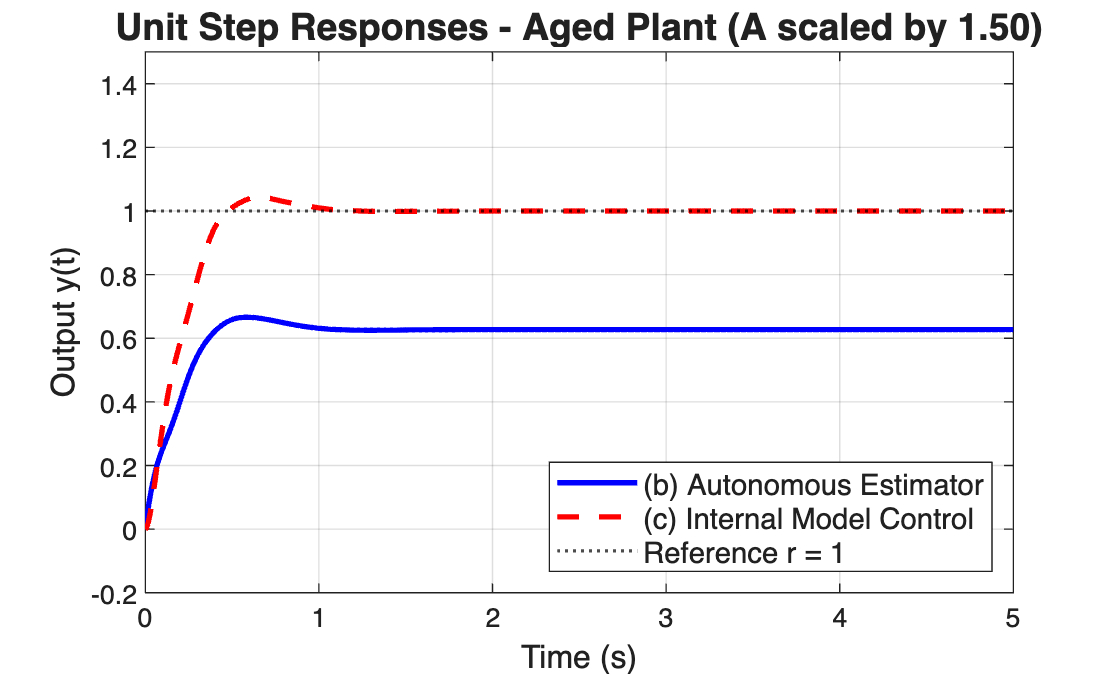


% Stability check
if any(real(eig(Acl_b_aged)) >= 0) || any(real(eig(A_aug_c_aged)) >= 0)
    warning('One of the aged closed-loop systems is unstable. Try a smaller aging factor.');
end

% Simulate
[y_b_aged, t_b_aged] = step(sys_b_aged, t);
[y_c_aged, t_c_aged] = step(sys_c_aged, t);

figure('Name','Part (e): Step Responses - Aged Plant (A x 1.5)','NumberTitle','off');
plot(t_b_aged, y_b_aged, 'b-',  'LineWidth', 2); hold on;
plot(t_c_aged, y_c_aged, 'r--', 'LineWidth', 2);
yline(1, 'k:', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)', 'FontSize', 12);
ylabel('Output y(t)', 'FontSize', 12);
title(sprintf('Unit Step Responses - Aged Plant (A scaled by %.2f)', aging_factor), 'FontSize', 14);
legend('(b) Autonomous Estimator', ...
       '(c) Internal Model Control', ...
       'Reference r = 1', ...
       'Location', 'southeast', 'FontSize', 11);
xlim([0 5]); ylim([-0.2 1.5]);


fprintf('Aged steady-state y_b(5s) = %.4f  (error = %.4f)\n', y_b_aged(end), 1 - y_b_aged(end));

Aged steady-state y_b(5s) = 0.6269  (error = 0.3731)


fprintf('Aged steady-state y_c(5s) = %.4f  (error = %.4f)\n', y_c_aged(end), 1 - y_c_aged(end));

Aged steady-state y_c(5s) = 1.0000  (error = 0.0000)
